# Cough-Signal Based COVID Feature Extraction

BME 3053C Group Project MATLAB Header and Live Script

Group Members:Jasmine Day, Zinia Basil, Ahmet Bilgili

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

April 12, 2021

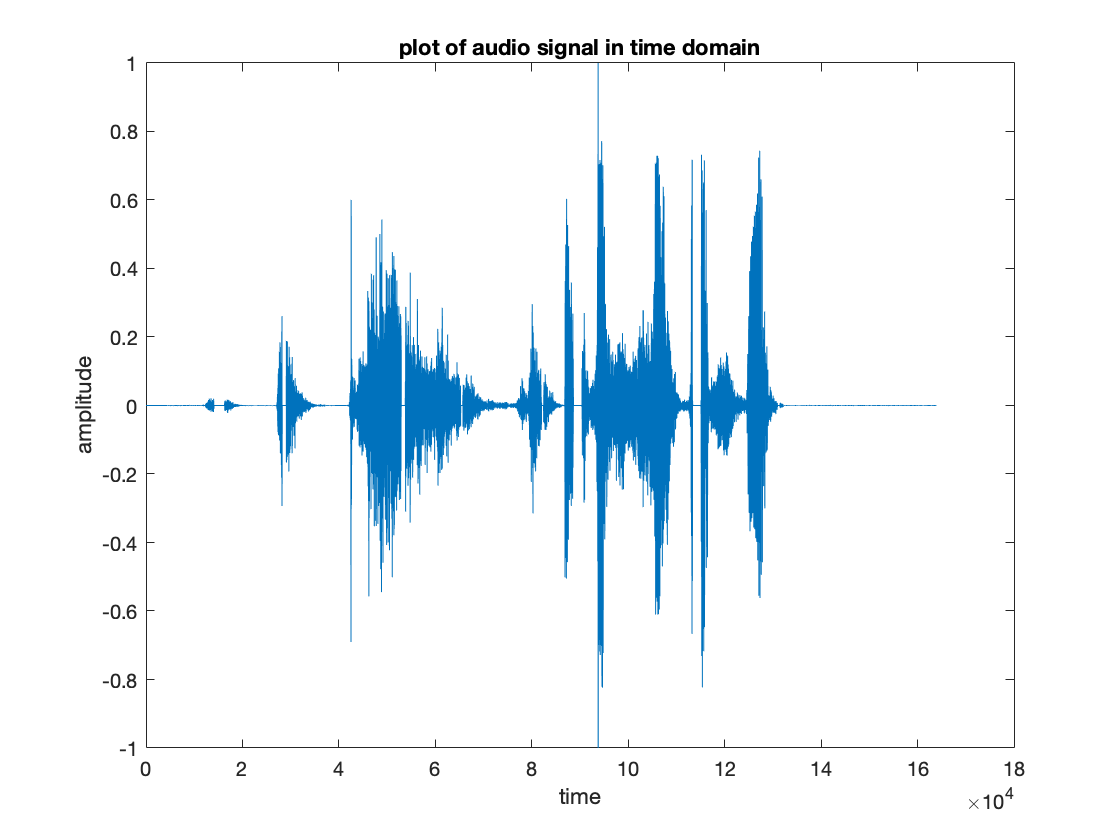

%Example of audio plot and mel frequency spectrogram for DEMO
[audio, fs]=audioread('cov1.wav');

sound(audio,fs);

plot(audio);
xlabel('time');
ylabel('amplitude');
title('plot of audio signal in time domain');

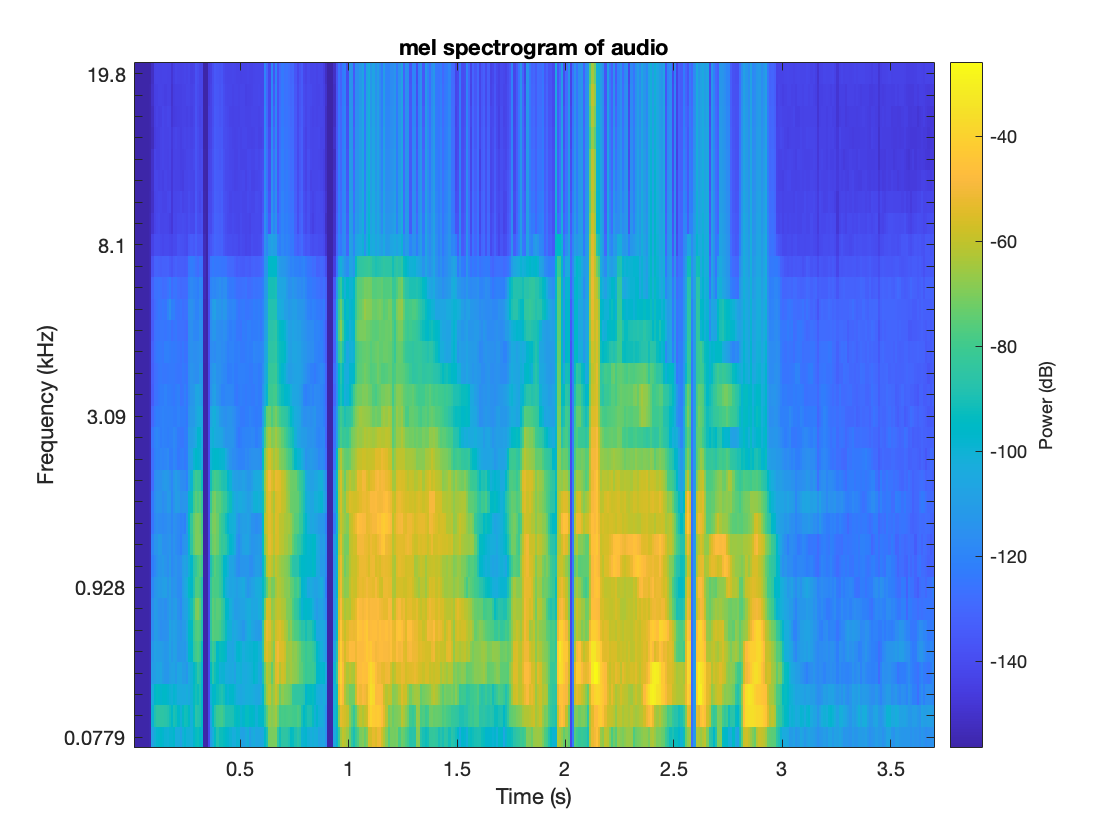



melSpectrogram(audio,fs)
title('mel spectrogram of audio');


% Load in audio .wav files
myDir = '/Users/jasmineday/Downloads/archive/trial_covid'; %gets directory
myFiles = dir(fullfile(myDir,'*.wav')); %gets all wav files in struct
mat=[];
xconcat=[];

for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    [x, fs] = audioread(fullFileName);
    
    %these are audio features that help create distinctions between signals
    aFE = audioFeatureExtractor( ...
    "SampleRate",fs, ...
    "Window",hamming(round(0.03*fs),"periodic"), ...
    "OverlapLength",round(0.02*fs), ...
    "mfcc",true, ...
    "pitch",true, ...
    "spectralCentroid",true, ...
    "spectralRolloffPoint", true, ...
    "spectralFlux", true, ...
    "spectralSpread", true, ...
    "spectralCrest", true, ...
    "spectralSlope", true, ...
    "spectralDecrease", true);
    
    features = extract(aFE,x);
    idx = info(aFE);

    pitch=mean(features(:,idx.pitch));
    specCentroid=mean(features(:,idx.spectralCentroid));
    mfcc=mean(features(:,idx.mfcc));
    specRolloff=mean(features(:,idx.spectralRolloffPoint));
    specFlux=mean(features(:,idx.spectralFlux));
    specSpread=mean(features(:,idx.spectralSpread));
    specCrest=mean(features(:,idx.spectralCrest));
    specSlope=mean(features(:,idx.spectralSlope));
    specDecrease=mean(features(:,idx.spectralDecrease));
    
    %Adds labels of whether the audio signal was covid-19 positive
    covid = 0;
    % the last 18 files in the directory are covid positive
    if k >= 148 
        covid = 1;
    end

    xconcat=[pitch, specCentroid, mfcc, specRolloff, specFlux, specSpread, specCrest, specSlope, specDecrease, covid];
    
    %vertical concatenation to build preprocessed data table
    mat = [mat ; xconcat];
end

% removes NaN values and replaces it with the mean of the column
means = mean(mat,'omitnan');
[row, col] = find(isnan(mat));
for ii = 1 : length(row)
    r = row(ii);
    c = col(ii);
    mat(r, c) = means(c);
end

data=array2table(mat);

save('featureData.mat','data');

